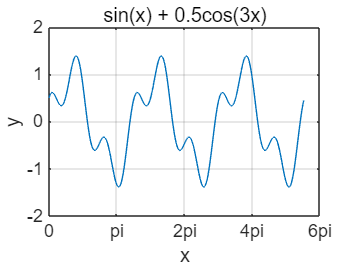

x = 0:0.05:6*pi;
y = sin(x) + 0.5*cos(3*x);

plot(x,y);
grid on;
title('sin(x) + 0.5cos(3x)');
xlabel('x');
ylabel('y');
xticklabels({'0', 'pi', '2pi', '4pi', '6pi'});

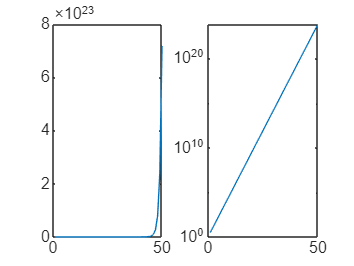

x = 1:1:50;
y = 3.^x;
subplot(1,2,1);
plot(x,y);
subplot(1,2,2);
semilogy(x,y);

일반 plot는 선형 스케일로 뒤로 갈수록 폭발적으로 커져서 x가 커짐에 따라 그래프가 갑자기 수직에 가깝게 치솟는 것처럼 보인다. semilogy는 로그스케일로 y축의 간격이 10의 거듭제곱 단위로 일정하게 증가하므로 x에 대한 1차 함수 형태가 된다.

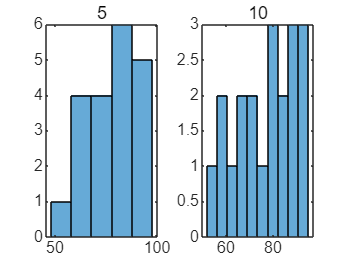

score = [72, 85, 91, 66, 78, 88, 95, 54, 60, 73, 82, 90, 69, 77, 84, 92, 58, 63, 79, 87];
save('score.dat', 'score', '-ascii');
load('score.dat');

figure;
subplot(1, 2, 1);
histogram(score, 5); 
title('5');

subplot(1, 2, 2);
histogram(score, 10);
title('10');

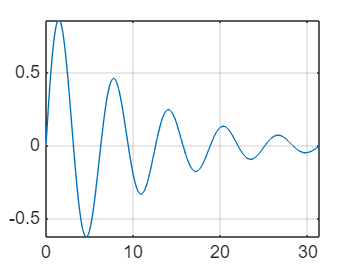

clc; clear;
figure;
fplot(@(x) sin(x).*exp(-0.1*x), [0, 10*pi]);
grid on;

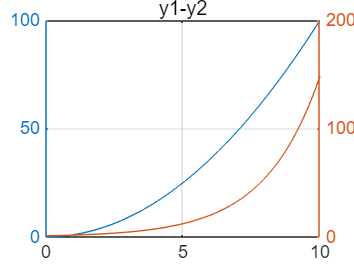

clc; clear;
figure;
x = 0:0.1:10;
y1 = x.^2;
y2 = exp(0.5.*x);

plotyy(x, y1, x, y2);
grid on
xlabel('x');
title('y1-y2');

그래프 초기 구간에서는 y1의 수치가 더 높아 보일 수 있으나, x가 커질수록 지수 함수인 y2의 증가율이 다항 함수인 y1을 압도하게 됩니다.

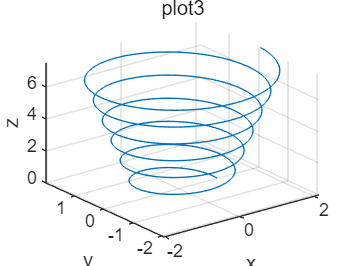

t = 0:0.02:12*pi;

x = (1+0.03.*t).*cos(t);
y = (1+0.03.*t).*sin(t);
z = 0.2.*t;

plot3(x,y,z);
title('plot3');
xlabel('x');
ylabel('y');
zlabel('z');
grid on;

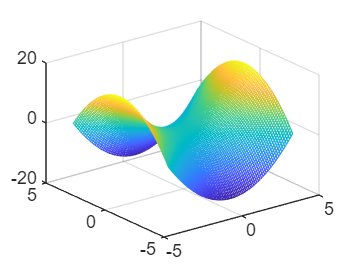

x = -4:0.1:4;
y = -4:0.1:4;
[x,y] = meshgrid(x,y);
z = x.^2 - y.^2;
figure;
mesh(x,y,z);
grid on;

극대와 극소가 공존하는 원점의 모습이 마치 말의 안장과 같은 saddle surface 이다. x축 방향에서 아래로 볼록한 곡선이 되고 y축 방향에서 위로 볼록한 곡선이 되므로 saddle surface 이다.

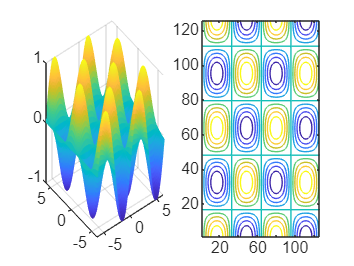

x = -2*pi:0.1:2*pi;
y = -2*pi:0.1:2*pi;
[x,y] = meshgrid(x,y);
z = sin(x).*cos(y);
figure;
grid on;
subplot(1,2,1);
mesh(x,y,z);
subplot(1,2,2);
contour(z);

3차원 구조의 데이터를 2차 평면에 나타내여 함수의 높이 변화를 시각적으로 보여준다.

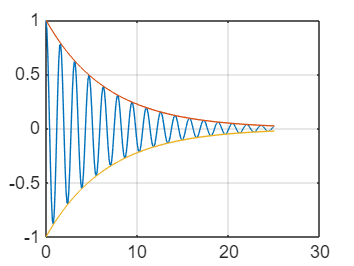

clc; clear;
t = 0:0.1:25;
y = exp(-0.15*t).*cos(4*t);
figure;
plot(t,y); hold on;
plot(t, exp(-0.15*t));
plot(t, -exp(-0.15*t));
grid on;

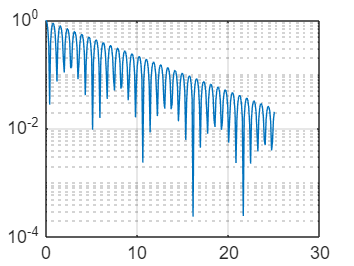

figure;
semilogy(t, abs(y));
grid on;

plot 에서는 곡선으로 보이던 감쇠 외곽선이 로그 스케일에서는 직선 형태로 나타난다.

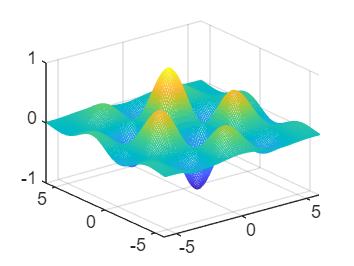

clc; clear;
x = -6:0.1:6;
y = -6:0.1:6;
[x,y] = meshgrid(x,y);
z = cos(x).*sin(y).*exp(-0.05.*(x.^2+y.^2));
figure;
mesh(x,y,z);

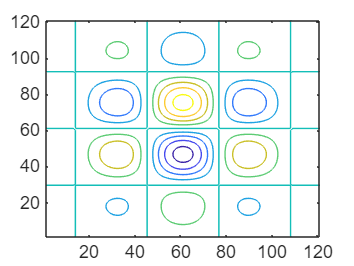

figure;
contour(z);


[max_val, idx] = max(z(:));
[row, col] = ind2sub(size(z), idx);
max_x = x(row, col);
max_y = y(row, col);
fprintf('최대값: %f\n', max_val);

최대값: 0.893457


fprintf('최대값 위치: (x = %f, y = %f)\n', max_x, max_y);

최대값 위치: (x = 0.000000, y = 1.400000)


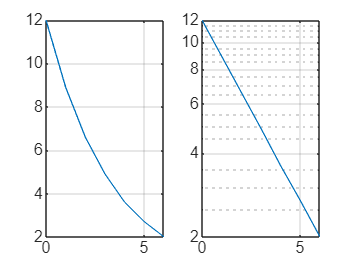

t = [0, 1, 2, 3, 4, 5, 6];
C = [12, 8.9, 6.6, 4.9, 3.6, 2.7, 2.0];

figure;
subplot(1, 2, 1);
plot(t, C);
grid on;

subplot(1, 2, 2);
semilogy(t, C);
grid on;


p = polyfit(t, log(C), 1); 

k_estimated = -p(1);
log_C0 = p(2);
C0_estimated = exp(log_C0);

fprintf('추정된 k값: %.4f\n', k_estimated);

추정된 k값: 0.2988


fprintf('추정된 C0값: %.4f\n', C0_estimated);

추정된 C0값: 11.9923


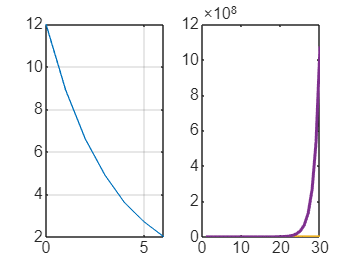

n = 1:1:30;
t1 = n;
t2 = n.*log(n);
t3 = n.^2;
t4 = 2.^n;

plot(n,t1, n,t2, n,t3, n,t4, 'LineWidth', 1.5);

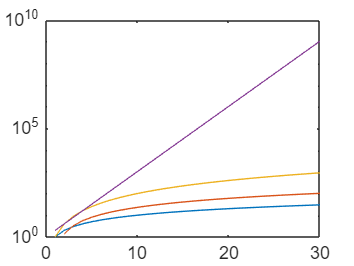

figure;
semilogy(n,t1, n,t2, n,t3, n,t4);

 다양한 차수의 다항 함수와 지수 함수가 섞여 있는 경우, 로그 스케일 그래프를 사용해야 각 함수의 고유한 성장 특성을 놓치지 않고 정확하게 비교할 수 있다.

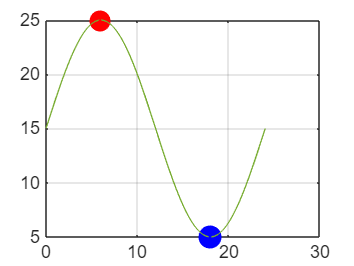

t = 0:0.1:24;

T = 15 + 10.*sin((pi.*t)/12);
plot(t, T); hold on;
grid on;

[max_T, max_idx] = max(T);
[min_T, min_idx] = min(T);

max_t = t(max_idx);
min_t = t(min_idx);

plot(max_t, max_T, 'ro', 'MarkerSize', 1, 'MarkerFaceColor', 'r');
plot(min_t, min_T, 'bo', 'MarkerSize', 1, 'MarkerFaceColor', 'b');

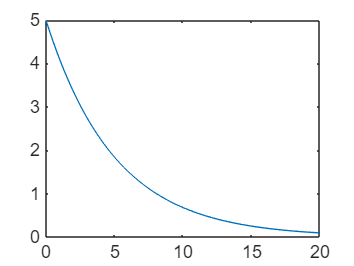

t = 0:0.1:20;
v = 5.*exp(-0.2.*t);

figure;
plot(t, v);

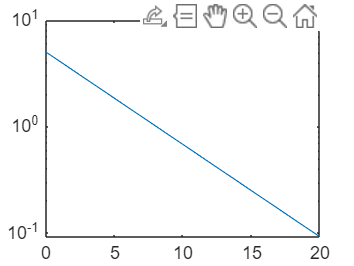

figure;
semilogy(t, v);

지수적으로 감소하는 현상을 다룰 때 일반 그래프는 실제 물리적인 양을 보여주고 로그 스케일 그래프는 감소하는 비율이 일정함을 보여준다.

A = [4 -1 2; 1 3 -1; 2 -2 5];
B = [7;4;10];

disp(A^2);

    19   -11    19
     5    10    -6
    16   -18    31



disp(A.^2);

    16     1     4
     1     9     1
     4     4    25



A^2 은 행렬 곱셉 규칙을 따르고 A.^2 은 각 위치의 원소를 각각 제곱한다

det(A)

ans = 43

det(A) 가 0 이 아니므로 역행렬이 존재한다.

inv(A)*B

ans =     1.0465
    1.7442
    2.2791


A\B

ans =     1.0465
    1.7442
    2.2791


inv(A)*B 는 A의 역행렬을 먼저 구한 뒤 B를 곱하고

A\B 는 가우스 소거법을 사용하여 직접 해를 구한다.

두 연산 모두 결과값은 동일하게 나온다

x = A\B;
disp(x);

    1.0465
    1.7442
    2.2791



A = [2 -1;3 4];
B = [1 0 -2; 3 5 1];
C = [6 -3 4; 15 14 -1];
X = A\(C-B);

Check = A*X + B;
disp(Check);

    6.0000   -3.0000    4.0000
   15.0000   14.0000   -1.0000



inv(A)는 역행렬을 직접 계산하는 과정에서 반올림 오차가 발생하지만 \ 연산자는 오차를 최소화하고 직접 해를 구하는 방식이 훨씬 빠르고 컴퓨터 자원을 적게 소모한다. 

X = [3 7 2 5; 5 9 4 6; 8 12 7 10; 10 15 9 13; 14 18 12 16];
mean(X)

ans =     8.0000   12.2000    6.8000   10.0000



Xc = X - mean(X)

Xc =    -5.0000   -5.2000   -4.8000   -5.0000
   -3.0000   -3.2000   -2.8000   -4.0000
         0   -0.2000    0.2000         0
    2.0000    2.8000    2.2000    3.0000
    6.0000    5.8000    5.2000    6.0000



S = Xc' *Xc

S =    74.0000   76.0000   68.0000   79.0000
   76.0000   78.8000   70.2000   82.0000
   68.0000   70.2000   62.8000   73.0000
   79.0000   82.0000   73.0000   86.0000


대각원소는 각 열의 제곱합을 나타내며 해당 데이터가 평균으로부터 얼마나 멀리 퍼져 있는지를 보여주는 분산에 비례하는 값이다. 

비대각원소는 두 변수 간의 교차곱 합을 나타내며 두 변수 사이의 상관관계를 보여주는 공분산에 비례하는 값이다.